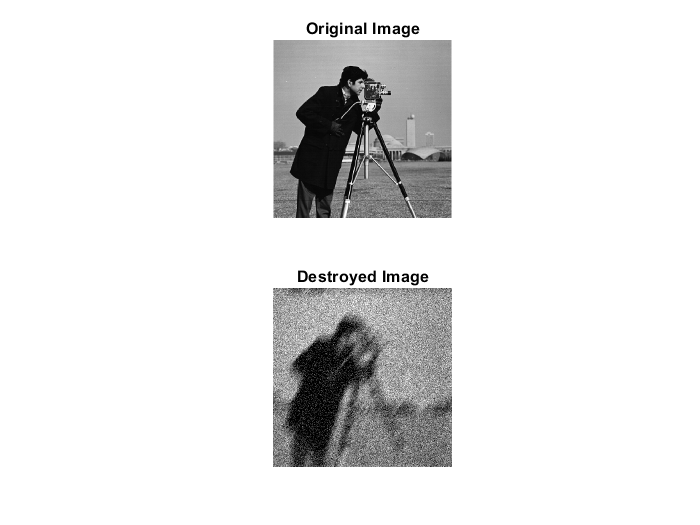

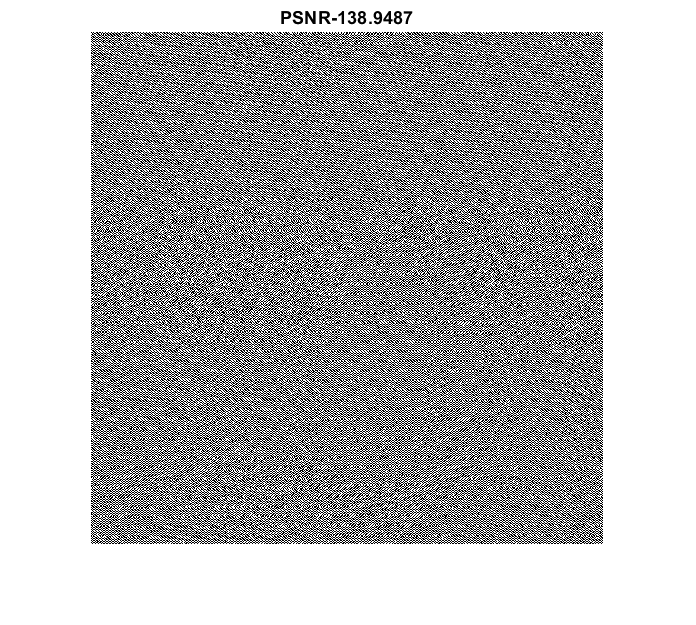

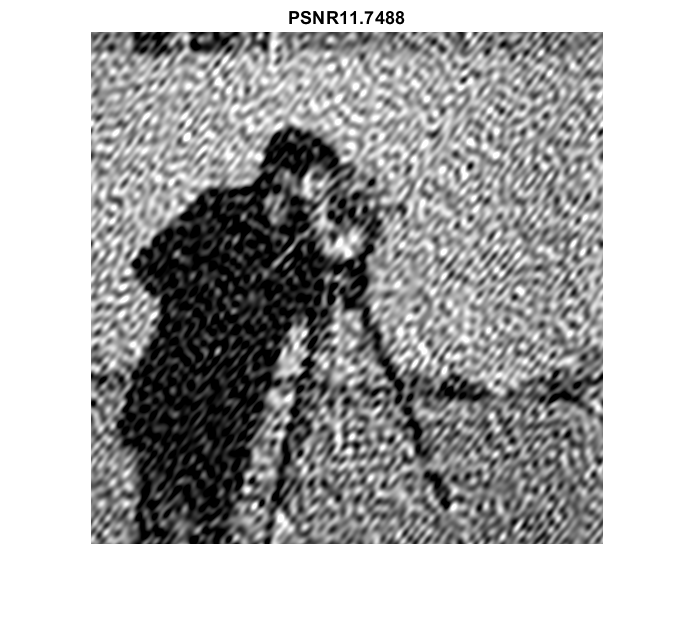

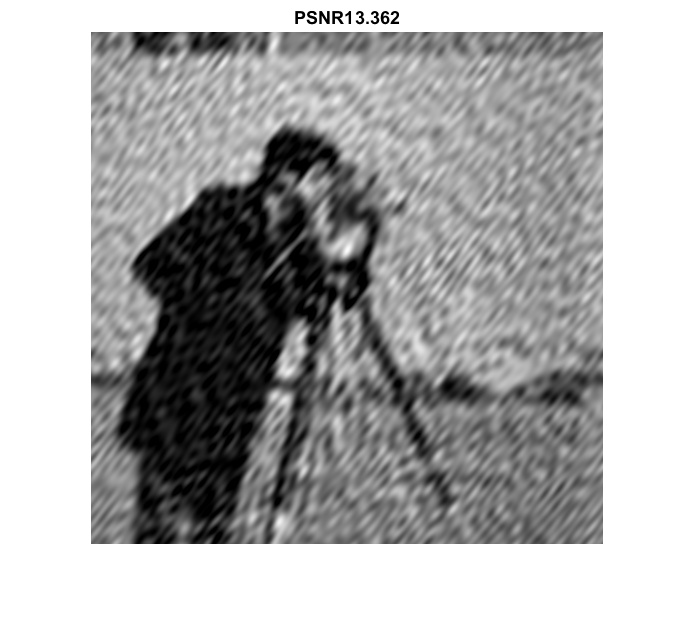

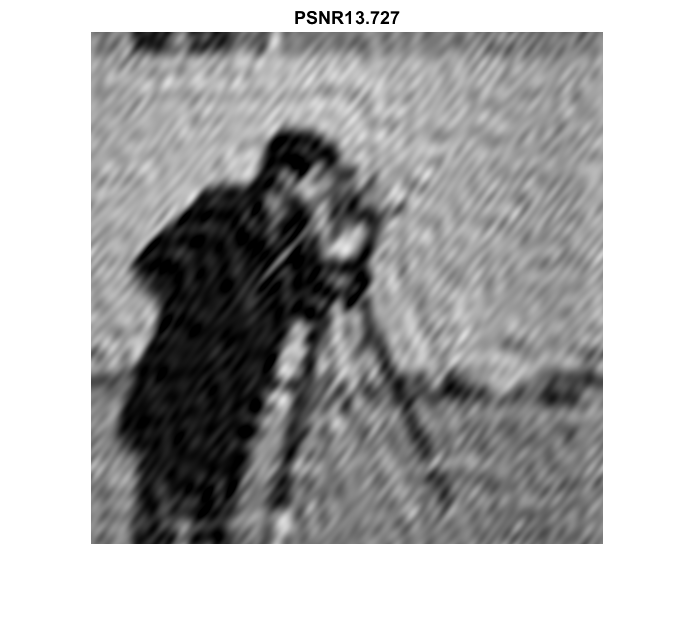

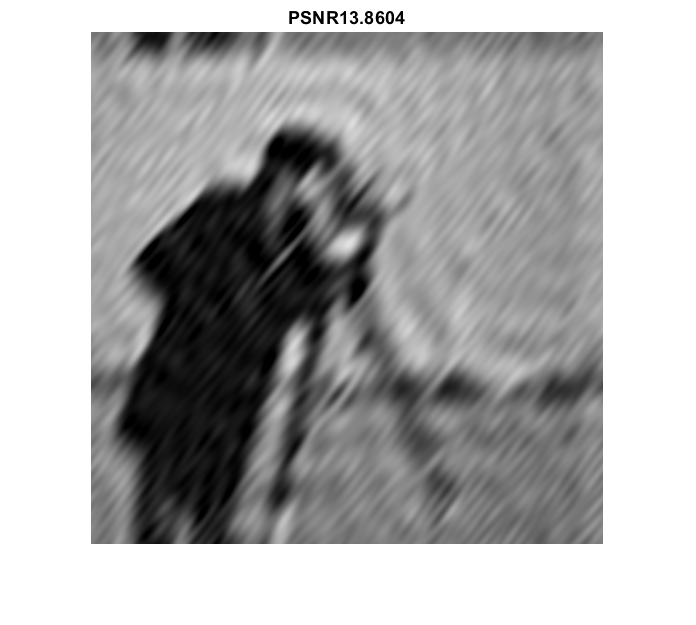

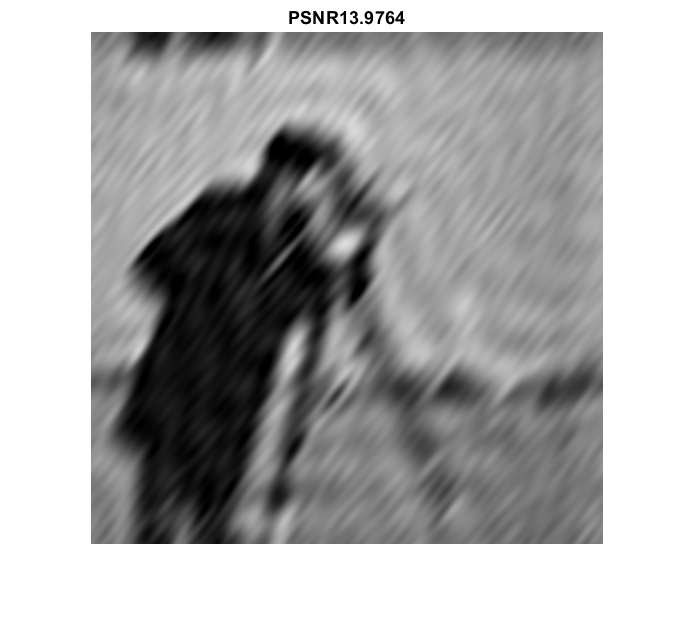

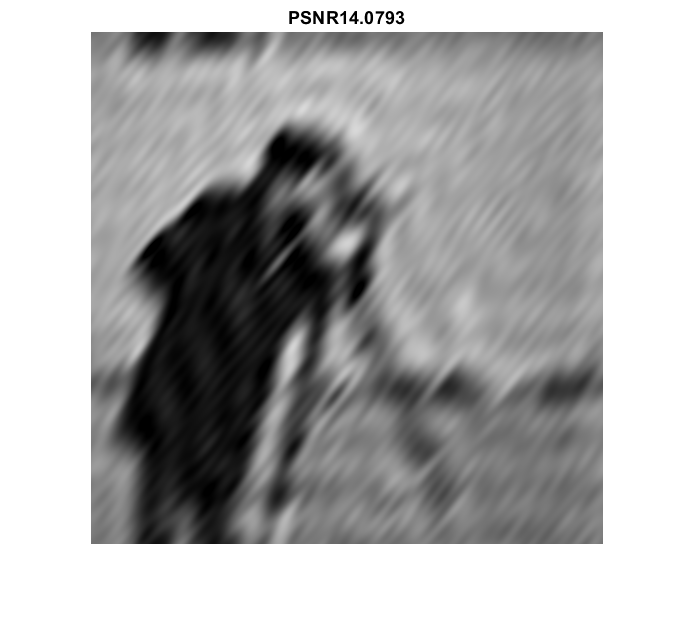

blurKernel = linearMotionBlurKernel;
noisy_image = cameraMan_blur_noise(:,:,2);
original_image = cameraMan_original;

figure;
subplot(2,1,1),imshow(original_image),title('Original Image')
subplot(2,1,2),imshow(noisy_image),title('Destroyed Image')


a = zeros(100,1);
i = 1;

for u = 0:0.05:0.95
    im = inverse_filter(noisy_image,blurKernel,u);
    a(i) = psnr(original_image,im,1);
    figure;
    imshow(im),title(['PSNR',num2str(a(i))])
    i = i + 1;
end